$F_c$ - driving force - $[N]$

$\eta_g$ - gearbox efficiency - $[-]$

$K_g$ - gear ratio - $[-]$

$r_{mp}$ - motor pinion radius (prumer pastorku) - $[m]$


$$F_c = \frac{\eta_g K_g \tau_M}{r_{mp}
}$$


$M_c$- mass of the cart - $[kg]$

$x_C$ - cart position - $[m]$

$B_{eq}$ - equivalent viscous damping coefficient - $[\frac{N m\; s}{rad}]$ 

clear all
close all
clc



eta_g = 0.9 %gearbox efficiency

eta_g = 0.9000

K_g = 3.71 %gearbox gear ratio

K_g = 3.7100

k_t = 7.68e-3 %motor current-torque constant

k_t = 0.0077

k_m = 7.68e-3 %motor back-emf constant

k_m = 0.0077

R_m = 2.6 %motor armature resistance

R_m = 2.6000

r_mp = 6.35e-3 %motor pinion radius (prumer pastorku)

r_mp = 0.0064

eta_m = 0.69 %motor efficiency

eta_m = 0.6900

A_m = eta_g * K_g * eta_m * k_t / r_mp / R_m %actuator gain

A_m = 1.0717

J_p = 1.2e-3 %moment of inertia about CoM, medium length pendulum

J_p = 0.0012

L_p = 0.3365 %full length of the pendulum

L_p = 0.3365

l_p = L_p/2

l_p = 0.1683

M_p = 0.127 %pendulum mass

M_p = 0.1270

%J_p = J_pCoM + M_p * l_p^2
M_c = 0.38 %cart mass

M_c = 0.3800

J_m = 3.9e-7 %motor moment of inertia

J_m = 3.9000e-07

J_eq = M_c + eta_g*K_g^2*J_m/r_mp^2

J_eq = 0.4998

B_eq = 4.3 %equivalent viscous damping coefficient (cart)

B_eq = 4.3000

B_p = 0.0024 %equivalent viscous damping coefficient (pendulum)

B_p = 0.0024

g = 9.81

g = 9.8100


syms x_c(t) alpha(t) V_m u

%sila pusobici na cart
F_c = (eta_g*K_g*k_t/R_m/r_mp)*(-K_g*k_m*diff(x_c,t)/r_mp + eta_m*V_m) %2.11 LinPendulumGantry

$$F\_c(t) = \frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{7785481995192533919\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$


%rovnice systemu (2.9 a 2.10 v LinearPendulumGantry)
disp("2.9 a 2.10")

2.9 a 2.10


ode1 = (J_eq+M_p)*diff(x_c,t,2) + M_p*l_p*cos(alpha)*diff(alpha,t,2) - M_p*l_p*sin(alpha)*diff(alpha,t)^2 == F_c - B_eq*diff(x_c,t)

$$ode1(t) = \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{4503599627370496}=\frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$

ode2 = M_p*l_p*cos(alpha)*diff(x_c,t,2) + (J_p+M_p*l_p^2)*diff(alpha,t,2) + M_p*l_p*g*sin(alpha) == -B_p*diff(alpha,t)

$$ode2(t) = \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{288230376151711744}+\frac{5528401504798809\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250}$$


ode1 = subs(ode1, V_m, u);
ode2 = subs(ode2, V_m, u);

odes = [ode1, ode2]

$$odes(t) = \begin{array}{l} \left(\begin{array}{cc} \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\sigma_{1}}{4503599627370496}=\frac{482657913448593747\,u}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000} & \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{288230376151711744}+\frac{5528401504798809\,\sigma_{2}}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

%odes = simplify(odes)

[V, S] = odeToVectorField(odes);

order = [3 1 4 2];
S = columnMatrixRearrange(S, order) %should = [ alpha Dalpha xc Dxc ]

$$S = \left(\begin{array}{c} x_{c}\\ \alpha \\ {\mathrm{Dx}}_{c}\\ \mathrm{Dalpha} \end{array}\right)$$

V = columnMatrixRearrange(V, order) 

$$V = \begin{array}{l} \left(\begin{array}{c} Y_{4}\\ Y_{2}\\ -\frac{2702600527374972243398096421103798125\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+1352674373017690692752698152207777792\,\cos\left(Y_{1}\right)\,Y_{2}+135550998138622756325414663090724008400\,u+118143497021674315858827754898758000000\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)-1425350728105450021100815047615317422080\,Y_{4}}{317500\,\sigma_{1}}\\ \frac{3010792482713412718070883237467104375\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+9920033739558007695949399027146031104\,Y_{2}+866422473835876089577635639302496000000\,\sin\left(Y_{1}\right)-1587891075259367506641974498084338503680\,\cos\left(Y_{1}\right)\,Y_{4}+151008601562165373061735538694788876400\,u\,\cos\left(Y_{1}\right)}{79375\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=37931243876704412196168607716121\,{\cos\left(Y_{1}\right)}^{2}-249699691576704713964325767118512 \end{array}$$


fh_tmp = matlabFunction(V, 'vars', {'t', 'Y', 'u'});
X = sym('x', [1 4]);
X = [X(order(end)), X(order(end-1)), X(order(end-2)), X(order(end-3))];
V = fh_tmp(t, X, u);
vpa(V,2);
X = sym('x', [1 4]);

A_sym = jacobian(V, X);
B_sym = jacobian(V, u);

disp([transpose(X)  S])

$$\left(\begin{array}{cc} x_{1} & x_{c}\\ x_{2} & \alpha \\ x_{3} & {\mathrm{Dx}}_{c}\\ x_{4} & \mathrm{Dalpha} \end{array}\right)$$

X_operating = [0, pi, 0, 0];
A = subs(A_sym, [X, u], [X_operating, 0]);
B = subs(B_sym, [X, u], [X_operating, 0]);

A = double(A)

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    1.7571  -21.1991   -0.0201
         0   51.5448  -94.4660   -0.5902


B = double(B)

B =          0
         0
    2.0160
    8.9837


C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = [0; 0; 0; 0]

D =      0
     0
     0
     0


linearSystem = ss(A,B,C,D);

disp("Poles:")

Poles:


eigs(A)

ans =   -21.7084
   -6.5742
    6.4934
         0



disp("Poles of a subsystem without x_C:")

Poles of a subsystem without x_C:


A_sub = A;
A_sub(1,:) = []; 
A_sub(:,1) = [];
eigs(A_sub)

ans =   -21.7084
   -6.5742
    6.4934


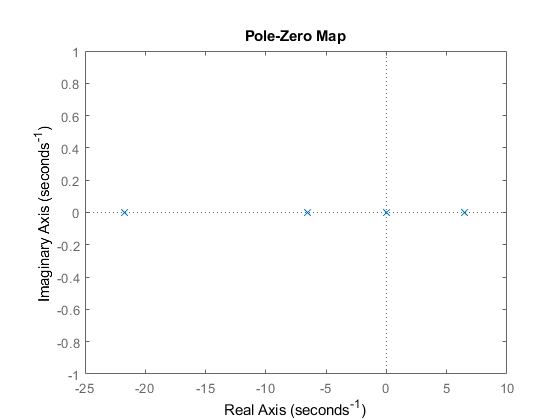


pzmap(linearSystem)

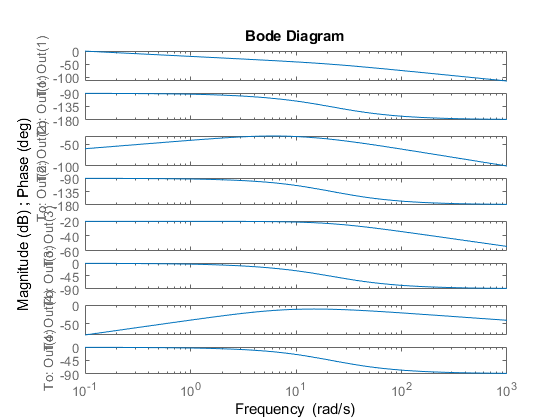

bode(linearSystem)

%p = [-3, -3.1, -3.2, -2.9]
p = [-2, -1.99, -1.98, -1.97]

p =    -2.0000   -1.9900   -1.9800   -1.9700


%p = [ -1, -0.99, -0.98, -0.97] nestaci
Kr_pp = place(A, B, p)

Kr_pp =    -0.1762    8.4487  -10.8722    0.8982


URO_poles = eig(A-B*Kr_pp)

URO_poles =    -2.0000
   -1.9900
   -1.9800
   -1.9700



Q = diag([5 5 0.1 0.1])

Q =     5.0000         0         0         0
         0    5.0000         0         0
         0         0    0.1000         0
         0         0         0    0.1000


R = 0.2

R = 0.2000

[Kr_lqr, S, P] = lqr(A, B, Q, R);
Kr_lqr

Kr_lqr =    -5.0000   47.0779  -22.8931    6.7203


P

P =    -0.4747
   -5.9834
   -6.8268
  -22.7243


initialCondition = [0, pi, 0, 0] % x alpha dx dalpha

initialCondition =          0    3.1416         0         0


simulationTime = 20;

tspan = 0:0.1:simulationTime;
solutionNonlinearPP = ode45(@(t, Y) pendulumCart(Y, -Kr_pp*(Y-[1; pi; 0; 0]),B_eq,B_p,J_eq,J_p,K_g,M_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,r_mp),...
    tspan, initialCondition);

   -0.1762

   -0.1762

   -0.1762

   -0.1764

   -0.1764

   -0.1765

   -0.1765

   -0.1768

   -0.1769

   -0.1777

   -0.1778

   -0.1780

   -0.1780

   -0.1795

   -0.1803

   -0.1840

   -0.1847

   -0.1855

   -0.1855

   -0.1929

   -0.1962

   -0.2125

   -0.2152

   -0.2185

   -0.2185

   -0.2476

   -0.2536

   -0.2760

   -0.2764

   -0.2728

   -0.2716

   -0.2632

   -0.2487

   -0.1714

   -0.1575

   -0.1299

   -0.1226

   -0.0572

   -0.0103

    0.2211

    0.2522

    0.3183

    0.3422

    0.4648

    0.5359

    0.8804

    0.9247

    1.0113

    1.0420

    1.2421

    1.3490

    1.8505

    1.8988

    2.0177

    2.0801

    2.2855

    2.3856

    2.8570

    2.9091

    3.0113

    3.0542

    3.2320

    3.3129

    3.6951

    3.7419

    3.8187

    3.8429

    4.0152

    4.0845

    4.4037

    4.4361

    4.4896

    4.5131

    4.6244

    4.6570

    4.8033

    4.8194

    4.8275

    4.8268

    4.8480

    4.8313

    4.7536

    4.7571

    

solutionNonlinearLQR = ode45(@(t, Y) pendulumCart(Y, -Kr_lqr*(Y-[1; pi; 0; 0]),B_eq,B_p,J_eq,J_p,K_g,M_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,r_mp),...
    tspan, initialCondition);

   -5.0000

   -4.9999

   -4.9999

   -4.9997

   -4.9997

   -4.9997

   -4.9997

   -4.9994

   -4.9992

   -4.9984

   -4.9983

   -4.9981

   -4.9981

   -4.9965

   -4.9957

   -4.9917

   -4.9910

   -4.9901

   -4.9901

   -4.9822

   -4.9782

   -4.9584

   -4.9549

   -4.9505

   -4.9505

   -4.9110

   -4.8915

   -4.7939

   -4.7767

   -4.7552

   -4.7553

   -4.5623

   -4.4710

   -4.0172

   -3.9363

   -3.8405

   -3.8449

   -3.6142

   -3.5068

   -2.9730

   -2.8764

   -2.7655

   -2.7743

   -2.5052

   -2.3826

   -1.7725

   -1.6590

   -1.5350

   -1.5517

   -1.2825

   -1.1617

   -0.5596

   -0.4458

   -0.3252

   -0.3460

   -0.1056

    0.0014

    0.5343

    0.6349

    0.7406

    0.7216

    0.9284

    1.0195

    1.4727

    1.5584

    1.6472

    1.6301

    1.7851

    1.8534

    2.1928

    2.2562

    2.3226

    2.3110

    2.4421

    2.4989

    2.7812

    2.8351

    2.8892

    2.8770

    2.9874

    3.0339

    3.2657

    3.3120

    

solTest = ode45(@(t, Y) pendulumCart(Y, 1.8*[0, 0, 0, -1]*Y,B_eq,B_p,J_eq,J_p,K_g,M_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,r_mp),...
    tspan, initialCondition);

     0

   2.2725e-16

   2.3871e-16

   1.5421e-15

   4.5682e-15

   6.4108e-15

   3.3107e-16

   2.2027e-15

  -2.5955e-15

   3.5002e-13

   2.9577e-12

   1.4620e-11

  -2.2771e-11

   3.2704e-10

  -5.5421e-09

   1.6087e-06

   4.0404e-05

   8.1839e-04

   -0.0073

   3.6951e-11

  -1.0936e-10

   7.1757e-09

   4.7920e-08

   1.6447e-07

  -1.4044e-07

   2.2781e-07

  -6.7438e-07

   4.4248e-05

   2.9549e-04

    0.0010

  -8.6598e-04

  -5.0142e-08

  -7.0307e-08

   5.0284e-07

   2.0137e-06

   2.7442e-06

  -1.1853e-07

  -4.2319e-08

  -5.9338e-08

   4.2439e-07

   1.6995e-06

   2.3161e-06

  -1.0003e-07

  -6.9595e-09

  -5.7845e-08

   1.1909e-06

   5.1532e-06

   8.2879e-06

  -8.6443e-07

  -8.7737e-08

  -4.8449e-07

   9.2001e-06

   3.9431e-05

   6.2282e-05

  -5.9747e-06

  -3.5624e-07

  -4.3825e-07

   2.2910e-06

   9.1077e-06

   1.2024e-05

  -4.3633e-07

  -1.7982e-07

  -2.2121e-07

   1.1564e-06

   4.5972e-06

   6.0694e-06

  -2.2024e-07

  -6.003

%[y, t, x] = lsim(linearSystemControlled, 0*t, simulationTime, initialCondition);
%solutionLinear = struct;
%solutionLinear.t = t;
%solutionLinear.x = x;

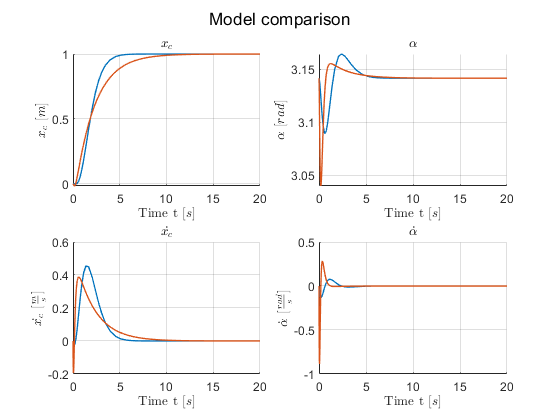


f1 = figure;
sgtitle("Model comparison")
subplot(221);
hold on
grid on
plot(solutionNonlinearPP.x, solutionNonlinearPP.y(1,:), "LineWidth", 1)
plot(solutionNonlinearLQR.x, solutionNonlinearLQR.y(1,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,1), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
  ylabel('$x_c$ [$m$]', 'Interpreter', 'Latex')
  title('$x_c$', 'Interpreter', 'Latex')
  
  subplot(222);
hold on
grid on
plot(solutionNonlinearPP.x, solutionNonlinearPP.y(2,:), "LineWidth", 1)
plot(solutionNonlinearLQR.x, solutionNonlinearLQR.y(2,:), "LineWidth", 1)
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
  ylabel('$\alpha$ [$rad$]', 'Interpreter', 'Latex')
  title('$\alpha$', 'Interpreter', 'Latex')
  
  subplot(223);
hold on
grid on
plot(solutionNonlinearPP.x, solutionNonlinearPP.y(3,:), "LineWidth", 1)
plot(solutionNonlinearLQR.x, solutionNonlinearLQR.y(3,:), "LineWidth", 1)
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
  ylabel('$\dot{x_c}$ [$\frac{m}{s}$]', 'Interpreter', 'Latex')
  title('$\dot{x_c}$', 'Interpreter', 'Latex')
  
  subplot(224);
hold on
grid on
plot(solutionNonlinearPP.x, solutionNonlinearPP.y(4,:), "LineWidth", 1)
plot(solutionNonlinearLQR.x, solutionNonlinearLQR.y(4,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,4), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
  ylabel('$\dot{\alpha}$ [$\frac{rad}{s}$]', 'Interpreter', 'Latex')
  title('$\dot{\alpha}$', 'Interpreter', 'Latex')